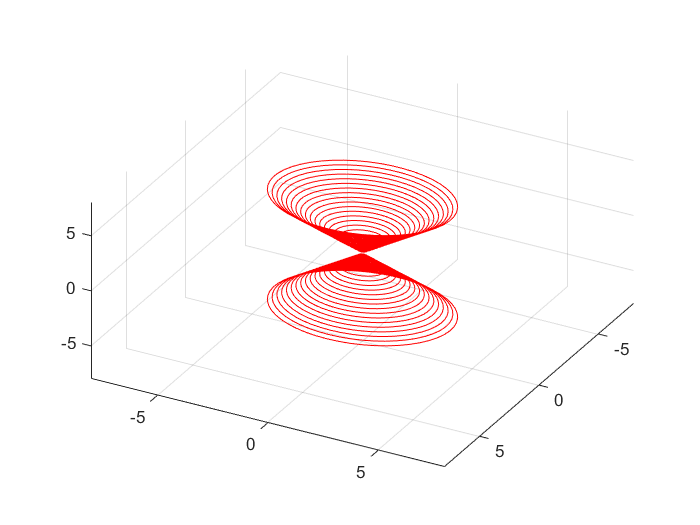

clc
hold on
axis ([-8 8 -8 8 -8 8])
axis on
grid on
view([0.4178 0.2247 0.5000])%设置摄像机位置
a=3;b=4;c=5;%设置abc的值
x=-a-5:a+5;
y=-b-5:b+5;
[X,Y]=meshgrid(x,y);
Z=zeros(size(X))+c;
pic_num = 1;
for i=1:100
if abs(Z(1))<=c 
h=mesh(X,Y,Z); %生成网格
k=sqrt((Z(1)).^2/c.^2);%中间变量k
Theta1=linspace(0,2*pi,50);
X1=a*k.*cos(Theta1);%每个曲线的参数方程
Y1=b*k.*sin(Theta1); 
Z1=zeros(length(X1))+Z(1);
g=plot3(X1,Y1,Z1,'r');%绘制曲线
else
break; 
end
Z=Z-1/4;
F=getframe(gcf);
I=frame2im(F);
[I,map]=rgb2ind(I,256);%制作动图
if pic_num == 1
    imwrite(I,map,'test2.gif','gif', 'Loopcount',inf,'DelayTime',0.2);
else
    imwrite(I,map,'test2.gif','gif','WriteMode','append','DelayTime',0.2);
end
pic_num = pic_num + 1;
delete(h);%删除上一个网格
end